% Presetting
PosExtract=[0; 0; 0; 1];

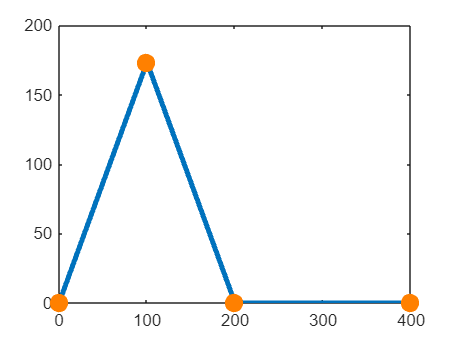

p =   Line - 속성 있음:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [1 0.5000 0]
              XData: [0 100.0000 200.0000 400.0000]
              YData: [0 173.2051 0 1.1102e-14]

  모든 속성 표시


% 3-DoF Manipulator Type1 Inverse Kinematics test by plot graph
EndpointPos = [400;0;0];

% Inverse Kinematics Solving
x = EndpointPos(1);
y = EndpointPos(2);
z = EndpointPos(3);
L1=200;
L2=200;
L3=200;
phi = 0;
xn = x - L3*cos(phi);
yn = y - L3*sin(phi);
theta2 = -acos((xn^2+yn^2-L1^2-L2^2)/(2*L1*L2));
theta1 = atan2(yn, xn) - atan2(L2*sin(theta2), L1+L2*cos(theta2));
theta3 = phi - (theta1 + theta2);

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = 0;
T01 = DHParameter(a0, alpha0, d1, theta1);

% Arm1 to Arm2
a1 = L1;
alpha1 = 0;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2);

% Arm2 to Arm3
a2 = L2;
alpha2 = 0;
d3 = 0;
T23 = DHParameter(a2, alpha2, d3, theta3);

% Arm3 to Endpoint
a3 = L3;
alpha3 = 0;
d4 = 0;
theta4 = 0;
T3E = DHParameter(a3, alpha3, d4, theta4);

%Base to Endpoint
T0E = T01*T12*T23*T3E;

% Base to Each Coordinate
T02 = T01*T12;
T03 = T01*T12*T23;
T0E = T01*T12*T23*T3E;

% Position of Each Coordinate according to Base Coordinate
p01=T01*PosExtract;
p02=T02*PosExtract;
p03=T03*PosExtract;
p0E=T0E*PosExtract;

% plot
p = plot([p01(1,1), p02(1,1), p03(1,1), p0E(1,1)],[p01(2,1), p02(2,1), p03(2,1), p0E(2,1)],'-o','LineWidth',3);
p.MarkerFaceColor = [1 0.5 0];
p.MarkerSize = 8;
p.MarkerEdgeColor = [1 0.5 0]